# Find *k*-Nearest Neighbors Using Different Distance Metrics

Find the 10 nearest neighbors in `X` to each point in `Y`, first using the Minkowski distance metric and then using the Chebychev distance metric.

Load Fisher's iris data set.

load fisheriris
X = meas(:,3:4);    % Measurements of original flowers
Y = [5 1.45;6 2;2.75 .75];  % New flower data

Perform a `knnsearch` between `X` and the query points `Y` using Minkowski and Chebychev distance metrics.

[mIdx,mD] = knnsearch(X,Y, ... %D stores distances
    'K',10, ...
    'Distance','minkowski', ...
    'P',5); %P is the exponent for Minkowski distance metric
[cIdx,cD] = knnsearch(X,Y, ...
    'K',10, ...
    'Distance','chebychev');

Visualize the results of the two nearest neighbor searches. 

Plot the training data. 

gscatter(X(:,1),X(:,2),species) %create scatterplot grouped by species

Plot the query points with the marker X. 

%query points
line(Y(:,1),Y(:,2), ...
    'Marker','x', ...
    'Color','k',...
   'Markersize',10, ...
   'Linewidth',2, ...
   'Linestyle','none')

Use circles to denote the Minkowski nearest neighbors.

%minkowski
line(X(mIdx,1),X(mIdx,2), ...
    'Color',[.5 .5 .5], ...
    'Marker','o',...
   'Linestyle','none', ...
   'Markersize',10)

Use pentagrams to denote the Chebychev nearest neighbors.

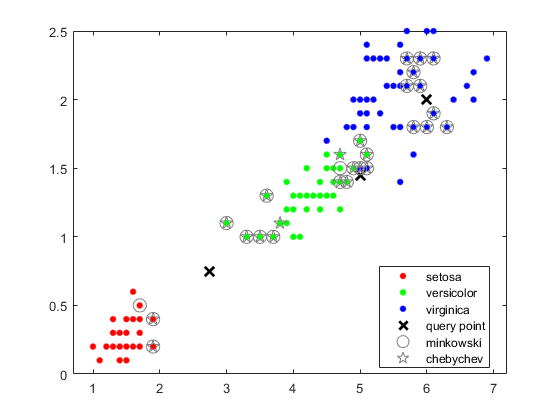

%chebychev
line(X(cIdx,1),X(cIdx,2), ...
    'Color',[.5 .5 .5], ...
    'Marker','p',...
   'Linestyle','none', ...
   'Markersize',10)

legend('setosa','versicolor','virginica','query point',...
'minkowski','chebychev','Location','best')

*Copyright 2015 The MathWorks, Inc.*